%Pattern Recognition Assignment 1
%authored by Md Juber Rahman
%date modified 10/02/2018
%analysis with normal distribution

%problem step 1 -generate 5 dimensional normally distributed data
% generate class 1 data
MU=[50 50 50 50 50];
SIGMA=[15 30 50 70 95];
gaussianMatrix1 = mvnrnd(MU,SIGMA,2000);
%Assign class label
gaussianMatrix1(:,6)=1;
% generate class 2 data
MU=[100 100 100 100 100];
SIGMA=[15 30 50 60 70];
gaussianMatrix2 = mvnrnd(MU,SIGMA,2000);
%Assign class label
gaussianMatrix2(:,6)=2;
% generate class 3 data
MU=[150 150 150 150 150];
SIGMA=[15 30 50 70 95];
gaussianMatrix3 = mvnrnd(MU,SIGMA,2000);
%Assign class label
gaussianMatrix3(:,6)=3;
% generate class 4 data
MU=[300 300 300 300 300];
SIGMA=[50 30 50 70 95];
gaussianMatrix4 = mvnrnd(MU,SIGMA,2000);
%Assign class label
gaussianMatrix4(:,6)=4;
% generate class 5 data
MU=[400 400 400 400 400];
SIGMA=[50 70 50 70 95];
gaussianMatrix5 = mvnrnd(MU,SIGMA,2000);
%Assign class label
gaussianMatrix5(:,6)=5;
gaussianMatrix=vertcat(gaussianMatrix1,gaussianMatrix2,gaussianMatrix3,gaussianMatrix4,gaussianMatrix5)

gaussianMatrix =    52.0824   51.6222   59.2321   45.8893   43.7085    1.0000
   57.1026   56.5770   56.9577   55.5031   47.1818    1.0000
   41.2515   55.9711   41.1514   62.0151   59.7509    1.0000
   53.3392   48.0353   48.7289   37.1570   44.2683    1.0000
   51.2346   49.2884   44.7433   64.6653   65.1805    1.0000
   44.9353   54.0188   51.6493   60.7348   36.7310    1.0000
   48.3207   50.6591   64.8588   50.7835   68.5197    1.0000
   51.3270   56.2239   43.8010   63.2201   51.7336    1.0000
   63.8591   46.2384   63.7800   52.0480   28.8825    1.0000
   60.7260   52.5835   46.7100   41.4639   56.8899    1.0000


%problem step 2
%compute co-variance matrix
gaussianData=gaussianMatrix(:,1:5);
coVarMatrix=cov(gaussianData)

coVarMatrix =    1.0e+04 *

    1.7034    1.6993    1.7007    1.7008    1.6984
    1.6993    1.7018    1.6994    1.6997    1.6972
    1.7007    1.6994    1.7058    1.7011    1.6985
    1.7008    1.6997    1.7011    1.7080    1.6988
    1.6984    1.6972    1.6985    1.6988    1.7053


% observations
% The co-variance matrix is symmetric
% the diagonal elements has higher values 
% the features are highly correlated


% problem step 3
% singular value decomposition
[U2,S2,V2] = svd(coVarMatrix,'econ');
% visualize original matrix
colormap('hot');

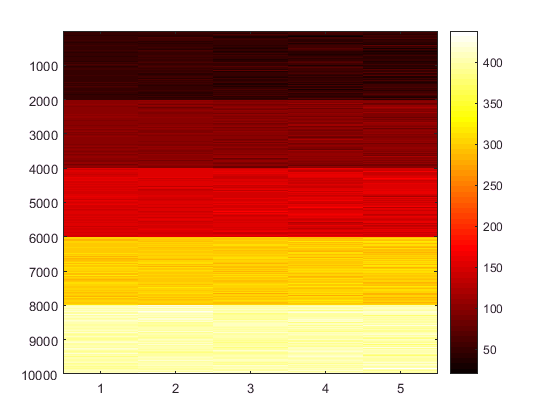

imagesc(gaussianData)
colorbar

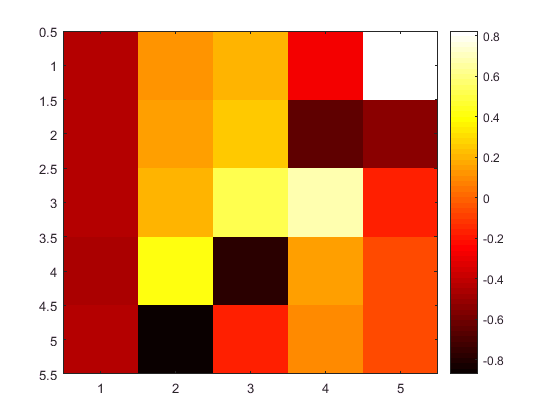

% visualize projected subspace
colormap('hot');
imagesc(V2)
colorbar

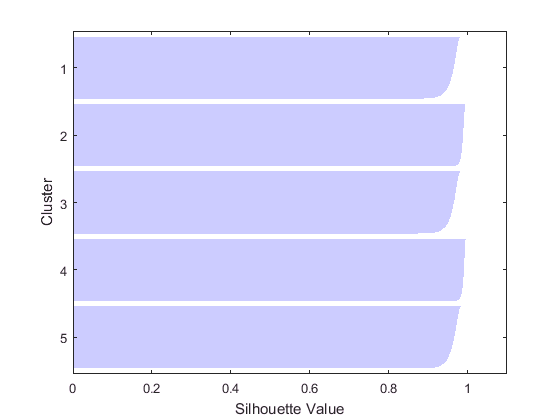

%problem step 4
% perform k-means clustering with euclidean
rng(1); % For reproducibility
[idx2,C] = kmeans(gaussianData,5);
figure
[silh52,h] = silhouette(gaussianData,idx2);
h = gca;
h.Children.EdgeColor = [.8 .8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'

%perform k means clustering with mahalanbish distance measure
rng(2); % For reproducibility
[idx,C] = kmedoids(gaussianData,5,'Distance','mahalanobis');
figure
[silh5,h] = silhouette(gaussianData,idx2);
h = gca;
h.Children.EdgeColor = [.8 .8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'

%problem step 5
Mdl = fitcknn(gaussianData,gaussianMatrix(:,6),'NumNeighbors',5);
rloss = resubLoss(Mdl)
%modify k
Mdl.NumNeighbors = 10;
loss = resubLoss(Mdl)
Mdl.NumNeighbors = 3;
loss = resubLoss(Mdl)
Mdl.NumNeighbors = 1;
loss = resubLoss(Mdl)

%k_means_(gaussianData, 5, 'euclidean')
%k_means_(gaussianData, 5, 'mahalanobis')

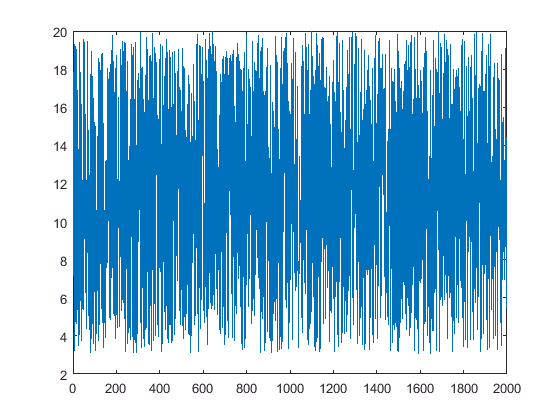

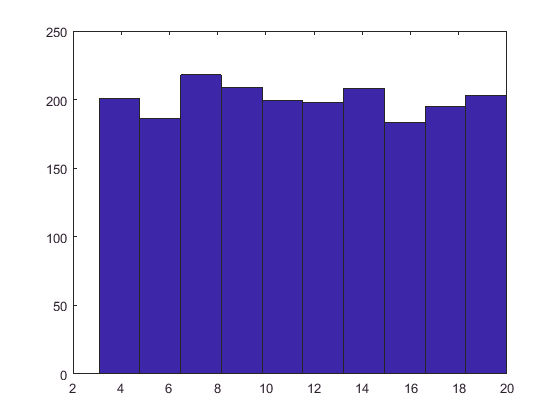

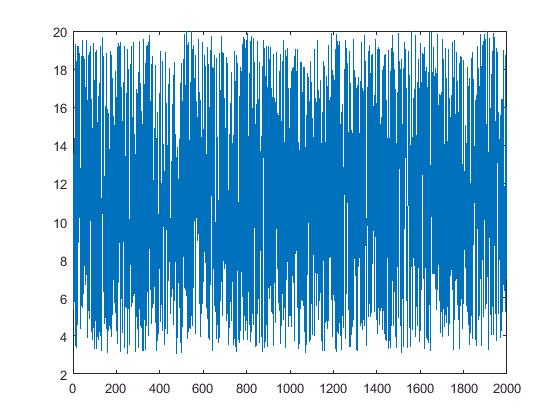

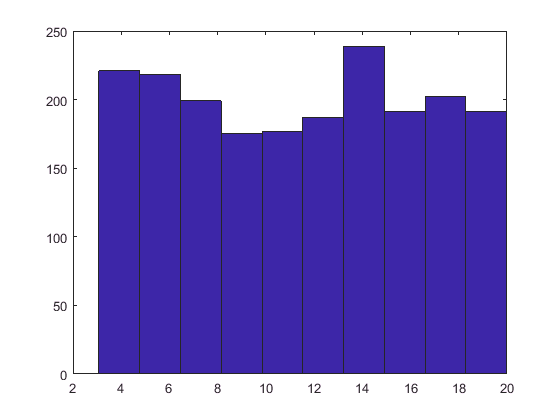

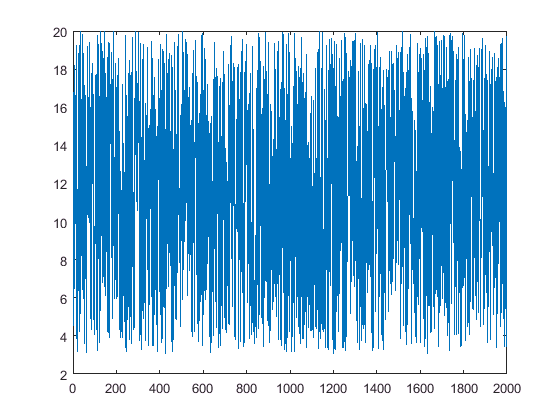

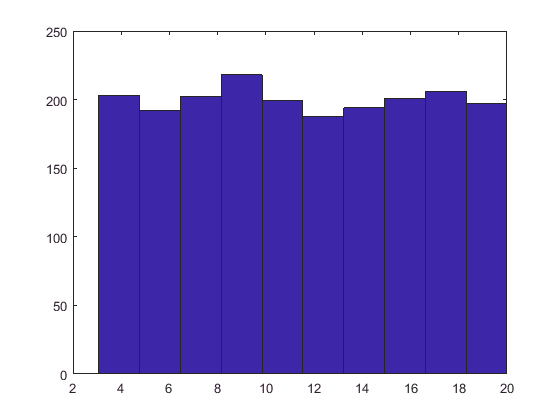

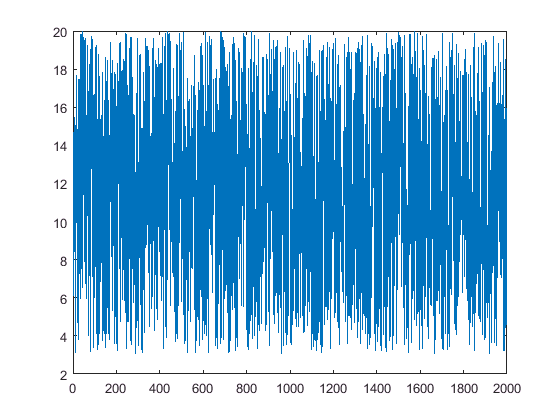

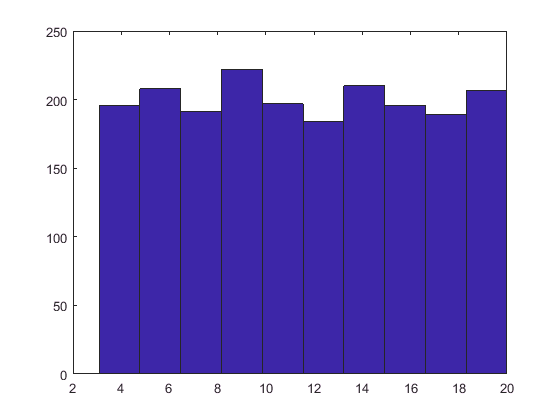

%generate uniformly distributed numbers
% specify the means
meanUniform=[10 20 30 40 50];
% specify the variance
varUniform=[4 8 12 16 20];

% get lower limit of uniform distributions
a1=((2*meanUniform(1))-varUniform(1)*sqrt(12))/2;
a2=((2*meanUniform(2))-varUniform(2)*sqrt(12))/2;
a3=((2*meanUniform(3))-varUniform(3)*sqrt(12))/2;
a4=((2*meanUniform(4))-varUniform(4)*sqrt(12))/2;
a5=((2*meanUniform(5))-varUniform(5)*sqrt(12))/2;
% get upper limit of uniform distributions
b1=((2*meanUniform(1))+varUniform(1)*sqrt(12))/2;
b2=((2*meanUniform(2))+varUniform(2)*sqrt(12))/2;
b3=((2*meanUniform(3))+varUniform(3)*sqrt(12))/2;
b4=((2*meanUniform(4))+varUniform(4)*sqrt(12))/2;
b5=((2*meanUniform(5))+varUniform(5)*sqrt(12))/2;
for i=1:5
x1(:,i)=a1 + b1*rand(2000,1);
x2(:,i)=a2 + b2*rand(2000,1);
x3(:,i)=a3 + b3*rand(2000,1);
x4(:,i)=a4 + b4*rand(2000,1);
x5(:,i)=a5 + b5*rand(2000,1);
figure
plot(x1(:,i));
%plot(x2(:,i));
%plot(x3(:,i));
%plot(x4(:,i));
%plot(x5(:,i));
figure
hist(x1(:,i));
%hist(x2(:,i));
%hist(x3(:,i));
%hist(x4(:,i));
%hist(x5(:,i));
end

%Assign class label
x1(:,6)=1;
x2(:,6)=2;
x3(:,6)=3;
x4(:,6)=4;
x5(:,6)=5;
%combine in a data matrix
completeMatrix=vertcat(x1,x2,x3,x4,x5);

%problem step 2
%compute co-variance matrix
dataMatrix=completeMatrix(:,1:5);
coVarMatrix=cov(dataMatrix);
disp(coVarMatrix);

  539.0132  270.8406  261.0454  269.9664  272.4199
  270.8406  528.9901  262.5623  266.3359  265.6864
  261.0454  262.5623  525.9790  267.3842  264.3488
  269.9664  266.3359  267.3842  538.7712  269.7825
  272.4199  265.6864  264.3488  269.7825  530.4534



% observations
% The co-variance matrix is symmetric
% the diagonal elements has higher values 
% the features are highly correlated


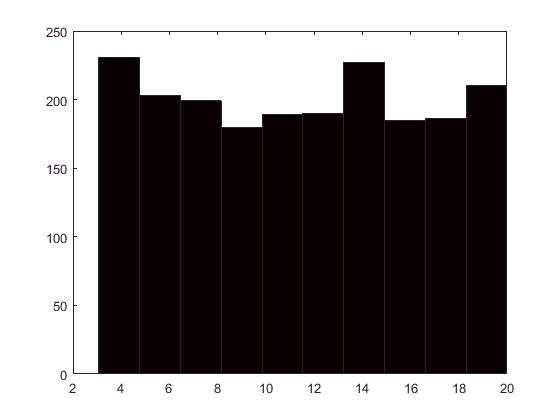

% problem step 3
% singular value decomposition
[U,S,V] = svd(coVarMatrix,'econ');
% visualize original matrix
colormap('hot');

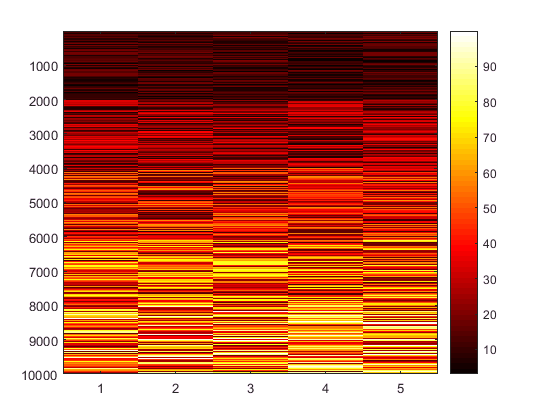

imagesc(dataMatrix)
colorbar

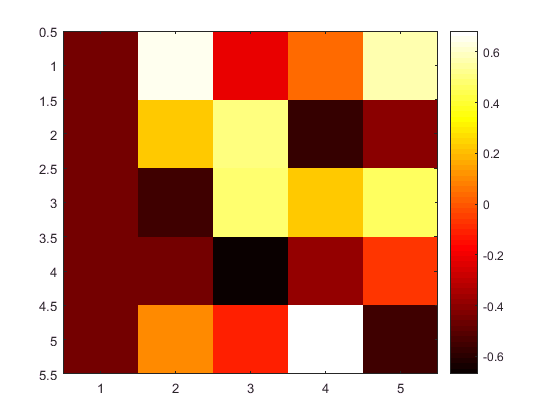

% visualize projected subspace
colormap('hot');
imagesc(V)
colorbar

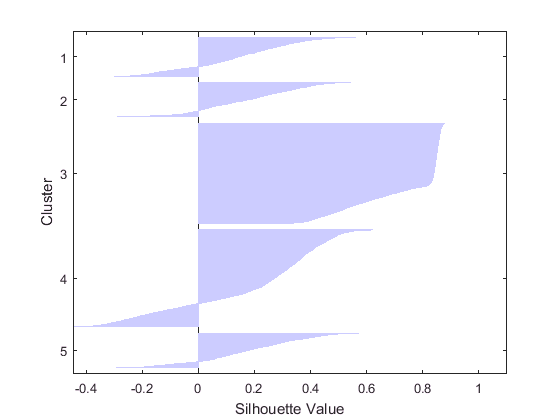

%problem step 4
% perform k-means clustering with euclidean
rng(1); % For reproducibility
[idx,C] = kmeans(dataMatrix,5);
figure
[silh5,h] = silhouette(dataMatrix,idx);
h = gca;
h.Children.EdgeColor = [.8 .8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'

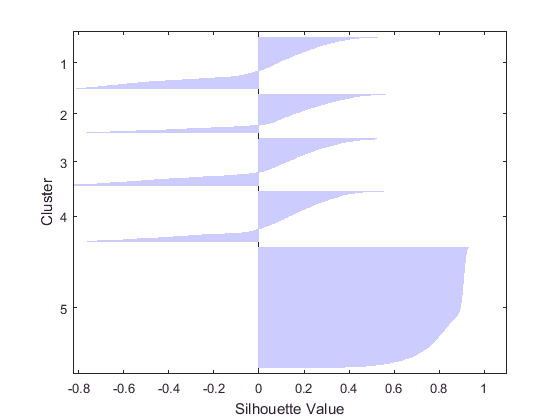

%perform k means clustering with mahalanbish distance measure
rng(2); % For reproducibility
[idx,C] = kmedoids(dataMatrix,5,'Distance','mahalanobis');
figure
[silh5,h] = silhouette(dataMatrix,idx);
h = gca;
h.Children.EdgeColor = [.8 .8 1];
xlabel 'Silhouette Value'
ylabel 'Cluster'

%problem step 5
Mdl = fitcknn(dataMatrix,completeMatrix(:,6),'NumNeighbors',5);
rloss = resubLoss(Mdl)

rloss = 0.1375

%modify k
Mdl.NumNeighbors = 10;
loss = resubLoss(Mdl)

loss = 0.1573

Mdl.NumNeighbors = 3;
loss = resubLoss(Mdl)

loss = 0.1176

Mdl.NumNeighbors = 1;
loss = resubLoss(Mdl)

loss = 0

%analysis with normal distribution
%{
%specify the means
meanGaussian=[20 50 80 110 140];

varGaussian=[4 8 16 32 64];

for i=1:5
y1(:,i)=meanGaussian(1).*randn(1000,1) + sqrt(varGaussian(1));
y2(:,i)=meanGaussian(2).*randn(1000,1) + sqrt(varGaussian(2));
y3(:,i)=meanGaussian(3).*randn(1000,1) + sqrt(varGaussian(3));
y4(:,i)=meanGaussian(4).*randn(1000,1) + sqrt(varGaussian(4));
y5(:,i)=meanGaussian(5).*randn(1000,1) + sqrt(varGaussian(5));
figure
plot(y1(:,i));
plot(y2(:,i));
plot(y3(:,i));
plot(y4(:,i));
plot(y5(:,i));
figure
hist(y1(:,i));
hist(y2(:,i));
hist(y3(:,i));
hist(y4(:,i));
hist(y5(:,i));
end
%}

%k_means_(dataMatrix, 5, 'euclidean')
%k_means_(dataMatrix, 5, 'mahalanobis')